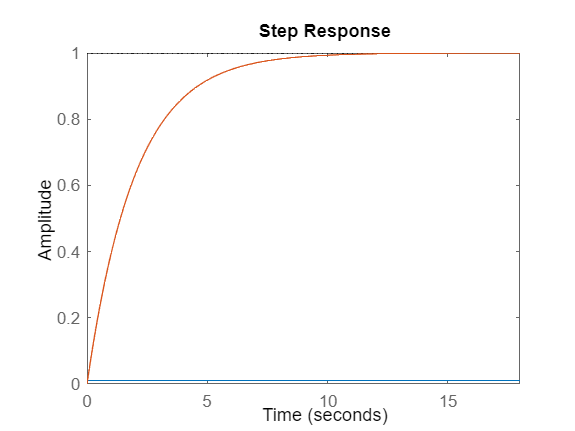

    clc, clear;
a = -100;
b = 1; 
c = 1; 
d = 0;
%steady state equation generation
sys = ss(a,b,c,d);
G = tf(ss);

%reference values
a_m = -0.5;
b_m = 0.5;

%learning parameters
Kx = (a_m - a)/b;
Kr = b_m/b;

sys_ref = ss(a_m, b_m, c, 0);
step(sys, sys_ref);